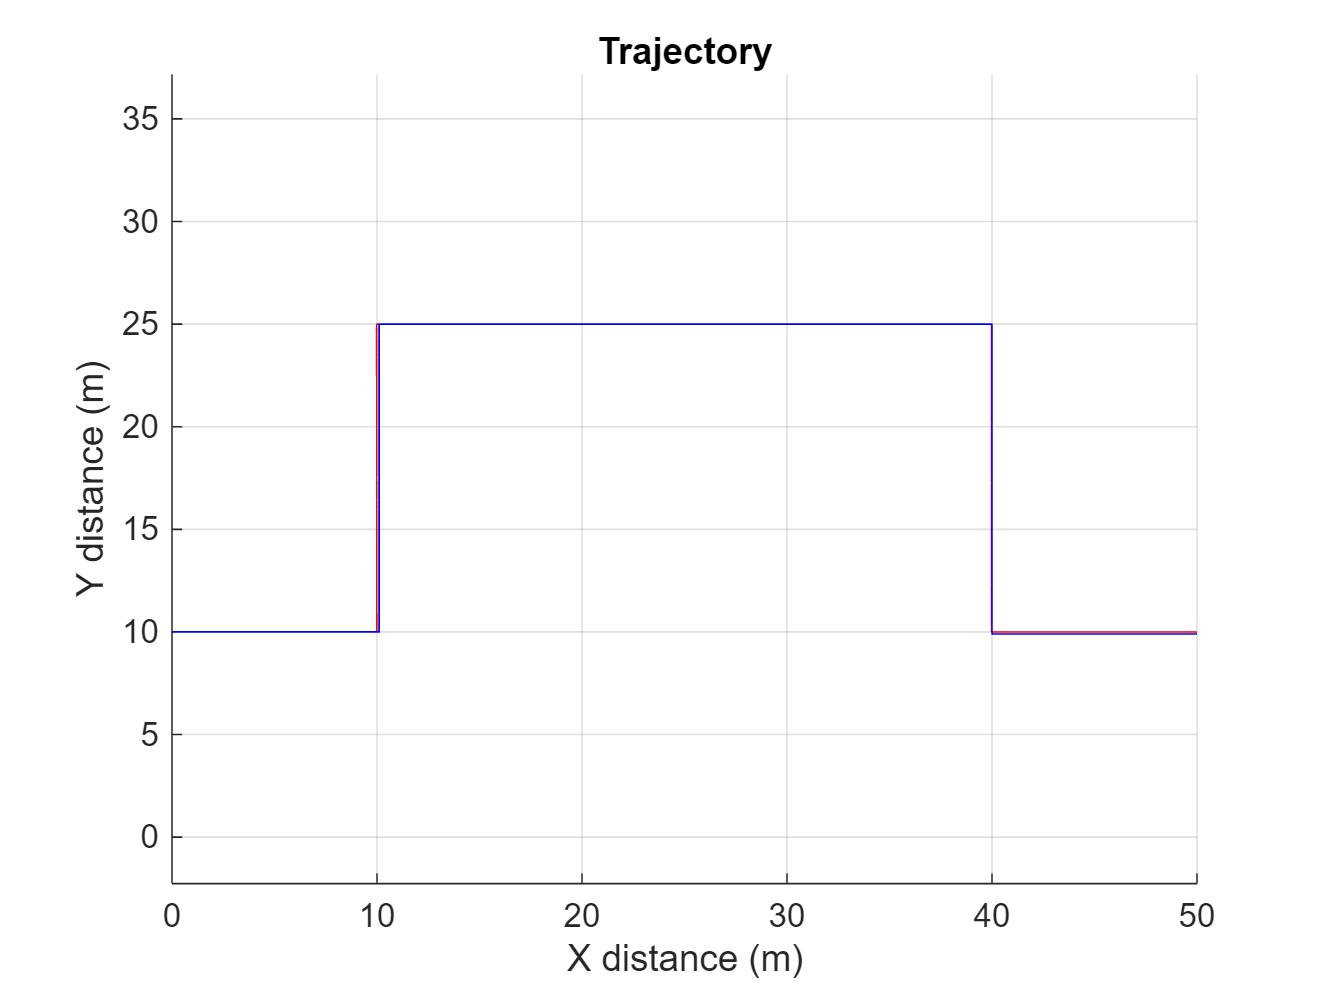


% ===== AUTHORS ===== %
% - Liam Murray
% - Sofia Simas
% - Lilly Mertzluft
% - Summer Chirpich
% - Satvik Kumar



% ===== INIT ========= %

clear
clc

[targetTime, targetPosX, targetPosY] = obstaclePath();
astrobee = generateAstrobeeStruct();
dt = 0.001;

% ===== SIMULATE ===== %

thrustProfiles = solveThrustProfiles(targetTime, targetPosX, targetPosY, astrobee, dt);
[time, posX, posY, velX, velY, theta, omega] = solvePath(astrobee, thrustProfiles);

% ===== DISPLAY ===== %
renderAnimation(time, targetTime, targetPosX, targetPosY, posX, posY, theta, thrustProfiles, astrobee);